Recll Positive判定したうちの正しくPositiveを出した割合: TP/P

Fallout 間違えてPositiveにした割合: FP/N

Precision Positiveのうちの正しくPositiveを出した割合: TP/P^

Accuracy 正しく推定した割合: TP+TN/P^ + N^

Recall(TP/P)=1 -> FN=0, P=TP

Fallout(FP/(TN+FP))=a

Precision(TP/TP+FP)=b

Accuracy(TP+TN/ALL)=TP+TN/TP+TN+FP+FN=TP+TN/TP+TN+FP=c

## Concept Check: Evaluating Classification Models

Q1. 95

Q2. Recall and Fallout

Q3. A model trained using the new cost matrix will have a higher recall for the class "No Crack."

## Project: Classifying Traffic Sign Images

% fileName = uigetdir;
fileName = 'C:\Users\kenconnor\Desktop\playground_matlab\Computer Vision for Engineering and Science\Data\Traffic Signs';
imdsSigns = imageDatastore(fileName,"IncludeSubfolders",true,"LabelSource","foldernames");
[imdsTrain,imdsTest] = splitEachLabel(imdsSigns,0.8,"randomized");
countEachLabel(imdsTrain)

ans = 4×2 table
           Label            Count
    ____________________    _____

    Do Not Enter             192 
    End All Restrictions     192 
    Road Closed              192 
    Yield                    192 


countEachLabel(imdsTest)

ans = 4×2 table
           Label            Count
    ____________________    _____

    Do Not Enter             48  
    End All Restrictions     48  
    Road Closed              48  
    Yield                    48  


bag = bagOfFeatures(imdsTrain,"GridStep",[2 2]);

Bag-Of-Features を作成しています。
-------------------------
* イメージ カテゴリ 1: Do Not Enter
* イメージ カテゴリ 2: End All Restrictions
* イメージ カテゴリ 3: Road Closed
* イメージ カテゴリ 4: Yield
* Grid メソッドを使用して特徴点の位置を選択します。
* 選択した特徴点の位置から SURF 特徴を抽出します。
** GridStep は [2 2]、BlockWidth は [32 64 96 128] です。

* 768 個のイメージから特徴を抽出しています...完了。2079104 個の特徴を抽出しました。

* 各カテゴリから最も強い特徴の 80 % を保持します。

* クラスタリング向上のため、すべてのイメージ カテゴリにわたって特徴の数を均衡化します。
** 最も強い特徴の数が最小なのはイメージ カテゴリ 1 です: 258637。
** 他の各イメージ カテゴリから 258637 個の最も強い特徴を使用します。

* 500 ワードのビジュアル ボキャブラリを作成します。
* レベルの数: 1
* 分岐因子: 500
* クラスタリング ステップの数: 1

* [ステップ 1/1] ボキャブラリ レベル 1 をクラスタリングします。
* 特徴の数 : 1034548
* クラスターの数 : 500
* クラスターの中心を初期化しています...100.00%.
* クラスタリングしています...100 回中 44 回の反復 (~3.94 seconds/iteration) を完了...44 回の反復で収束しました。

* Bag-Of-Features の作成が完了しました。



predFeats = encode(bag,imdsTrain);

Bag-Of-Features を使用してイメージをエンコードします。
--------------------------------------
* イメージ カテゴリ 1: Do Not Enter
* イメージ カテゴリ 2: End All Restrictions
* イメージ カテゴリ 3: Road Closed
* イメージ カテゴリ 4: Yield
* 768 個のイメージをエンコードしています...完了。


featNames = "f" + string(1:500);
predTable = array2table(predFeats,"VariableNames",featNames);
predTable.labels = categorical(imdsTrain.Labels);
predFeatsTest = encode(bag,imdsTest);

Bag-Of-Features を使用してイメージをエンコードします。
--------------------------------------
* イメージ カテゴリ 1: Do Not Enter
* イメージ カテゴリ 2: End All Restrictions
* イメージ カテゴリ 3: Road Closed
* イメージ カテゴリ 4: Yield
* 192 個のイメージをエンコードしています...完了。


predTableTest = array2table(predFeatsTest,"VariableNames",featNames);
predTableTest.labels = categorical(imdsTest.Labels);

classificationLearner

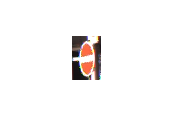

img = readimage(imdsTrain,10);
imshow(img)

size(img)

ans =     44    29     3


## [Quiz] Project: Classifying Traffic Sign Images

Q1. 192

Q2. 500

Q3. 1.6 (93.8-92.2)

Q4. End All Restrictions

Q5. 0.985

Q6. Fine KNN

Q7. Quadratic SVM

### 2回目。Hand-Selected Featuresを加えて精度が良くなるか？

handSelectedTable = extractHandSelectedRoadSignFeatures(imdsTrain);
predTable = horzcat(predTable, handSelectedTable);
handSelectedTableTest = extractHandSelectedRoadSignFeatures(imdsTest);
predTableTest = horzcat(predTableTest,handSelectedTableTest)

predTableTest = 192×505 table
       f1          f2           f3           f4           f5           f6           f7           f8          f9           f10          f11          f12         f13          f14          f15          f16          f17          f18          f19          f20          f21          f22         f23          f24         f25          f26          f27          f28         f29          f30          f31          f32          f33          f34          f35          f36          f37          f38          f39          f40          f41          f42         f43       f44       f45          f46          f47          f48          f49          f50          f51          f52          f53          f54          f55          f56          f57          f58         f59          f60          f61          f62          f63          f64          f65         f66          f67          f68         f69         f70          f71          f72         f73          f74         f75         f76     

classificationLearner